# Frequency Response

#### Define R and L OR C values

R=10;
L=20;
% C=30;

#### Choose respective $\omega_0$ constant

%% Comment the other out
w0=R/L;
% w0=1/(R*C);

#### Specify angular frequency range

w = 0:0.01:100;

#### Create transfer function, magnitude and phase

%% Scroll down to change transfer function definition
H = transfer(w, R, L);
%% See end for function definitions
mag = magnitude(H);
pha = phase(H);

#### Plot them, showing where $\omega_0$ is

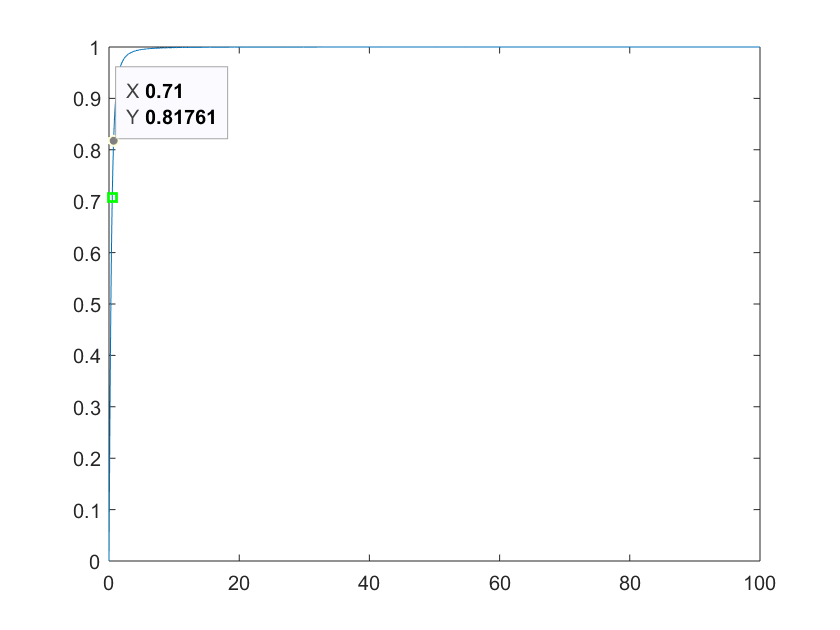

figure('Name','Magnitude');
plot(w,mag);
hold on;
plot(w0, magnitude(transfer(w0,R,L)),'gs','LineWidth',2);
figure('Name','Phase');

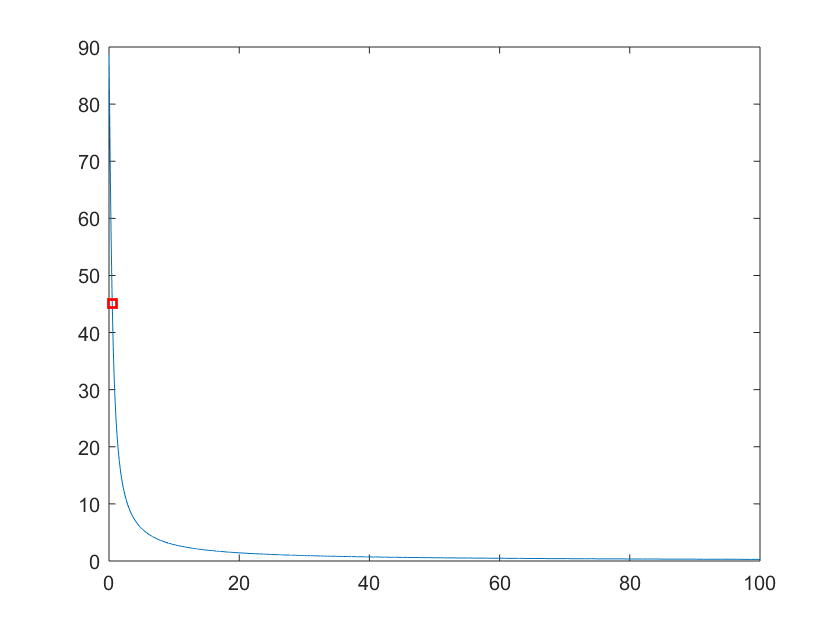

plot(w,pha);
hold on;
plot(w0, phase(transfer(w0,R,L)),'rs','LineWidth',2);

## Specify Transfer Function

function H = transfer(w, R, L)
    s = sqrt(-1)*w;
    H = s*L./(s*L+R);
end

#### The functions to get magnitude and phase

function m = magnitude(H)
    m = sqrt((real(H)).^2 + (imag(H)).^2);
end

function p = phase(H)
    p = atan(imag(H)./real(H)) * 180/pi;
end